# Linear Weights Calculation

First thing first, we load the 100 processed Sintel frames and extract the dataMat Matrix that contains the relevant outputs and inputs of the pipe [psnr,duty_cycle,max_val,IR, depth_pipe,depth_gt]. 

addpath(genpath('\\tmund-MOBL1.ger.corp.intel.com\c$\source\IVCAM\Algo\LIDAR'))
addpath(genpath('\\tmund-MOBL1.ger.corp.intel.com\c$\source\IVCAM\Algo\Common'))
%% Load processed sintel data
load('X:\Users\tmund\pipeOut.mat')
%% concat all the relevant paramters from processed frames into a dataMat
n_pixels = numel(results(1).gt.zImg); % number of pixels in image
dataMat = zeros(length(results)*n_pixels,6);
for i=1:length(results)
    depth_gt = single(results(i).gt.zImg);
    depth_pipe = single(results(i).zImgRAW/8);
    IR = single(results(i).iImgRAW);
    dutyCycle = single(results(i).dutyCycle);
    psnr = single(results(i).psnr);
    maxVal = single(results(i).max_val);
    dataMat(1+(i-1)*n_pixels:i*n_pixels,:) = [psnr(:),maxVal(:),dutyCycle(:),IR(:),depth_pipe(:),depth_gt(:)];
end

% Filter pixels with depth above 3500mmmax
filter_distant_pixels = false;
if filter_distant_pixels
    dataMat = dataMat(dataMat(:,6)<3500,:);
end
% Filter pixels with ir == 0 (invalid)
dataMat = dataMat(dataMat(:,4)>0,:);


Using matlabs Classification Learner application, a linear logistic regression model was previously trained. Reload it.

% Load pretrained classifier
load('logisiticRegressionClassifer.mat');

## Classifier Performance

Now we shall apply the classifier to our data and get a sense of its performance.

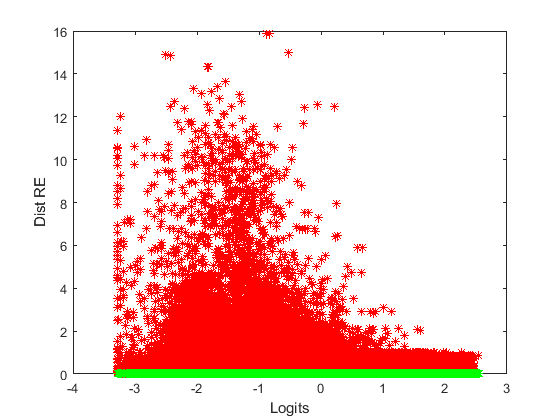

depthError = abs(dataMat(:,5)-dataMat(:,6))./abs(dataMat(:,6));
labels = double(depthError <= 0.01);
W = trainedClassifier.GeneralizedLinearModel.Coefficients{1:4,1};
getLogits = @(X)  X*W(2:4)+W(1);
logits = getLogits(dataMat(:,2:4));
[logits_sort,order] = sort(logits);
depthErrorSort = depthError(order);
labelsSort = labels(order);
plot((logits_sort(labelsSort==0)),depthErrorSort(labelsSort==0),'r*' )
hold on 
plot((logits_sort(labelsSort==1)),depthErrorSort(labelsSort==1),'g*' )
xlabel('Logits'); ylabel('Dist RE');
hold off

As can be seen above, the result of the classifer have a negative correlation with the relative error. In order to use the classifier in the pipeline we need to adjust it to fit the scaled data. 

By scaling the input data, the relevant scales should be scaled as well. This result in the following weights:

scaleVec = [1,2^2,2^-6];
inputData = cast(floor(dataMat(:,2:4).*scaleVec),'int16');
W_scaled = ([W(1); W(2:4)./scaleVec'])

W_scaled =    -1.6959
    0.0560
    0.0133
   -0.0249


Since the weights should be represented as int8, we need to scale the weights up to be integers between -128 and 127. I'll use the maximal scale up in order to decrease the error after rounding the number to integers. 

Because of hardware limitations, the bias will be used implicitly (through the activation function) and will be ignoed currently.

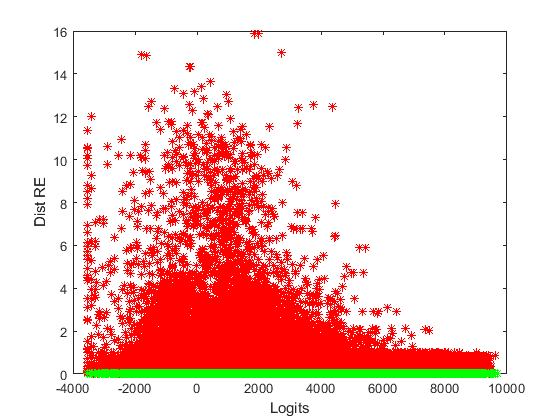

W_max = max(abs(W_scaled(2:4)));
W_final = cast(W_scaled*127/W_max,'int16');
getLogits = @(X)  double(X)*double(W_final(2:4));
logits = cast(getLogits(inputData),'int16');
[logits_sort,order] = sort(logits);
depthErrorSort = depthError(order);
labelsSort = labels(order);
plot(logits_sort(labelsSort==0),depthErrorSort(labelsSort==0),'r*' )
hold on 
plot((logits_sort(labelsSort==1)),depthErrorSort(labelsSort==1),'g*' )
xlabel('Logits'); ylabel('Dist RE');
hold off

In the conf block, the multiplication results is mapped to the range [-128.127]. Let us do it:

minActIn1 = -63*56;
maxActIn1 = 63*127 + 63*30;
dtAct1 = int16(maxActIn1-minActIn1);
x0Act1 = int16(minActIn1);
actOut1 = int8(((int32(logits)-int32(x0Act1))*255)/int32(dtAct1)-128);

Now we shall pass the last activation that will map the logits from [-128,127] to [0,255]:

minActIn2 = -128;
maxActIn2 = 127;
dtAct2 = int16(maxActIn2-minActIn2);
x0Act2 = int16(minActIn2);
actOut2 = uint8(((int32(actOut1)-int32(x0Act2))*255)/int32(dtAct2));

Now we apply bit shift 4 and take max(in,1):

conf = idivide(actOut2,2^4,'floor');
conf(conf<1) = 1;

Plot the relation between the resulting confidence and the depthError:

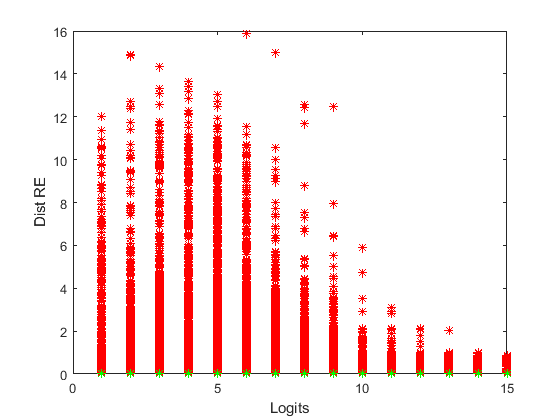

[logits_sort,order] = sort(conf);
depthErrorSort = depthError(order);
labelsSort = labels(order);
plot((logits_sort(labelsSort==0)),depthErrorSort(labelsSort==0),'r*' )
hold on 
plot((logits_sort(labelsSort==1)),depthErrorSort(labelsSort==1),'g*' )
xlabel('Logits'); ylabel('Dist RE');
hold off

# Classifier Evaluation

Let us plot the True Positive / True Negative rate:

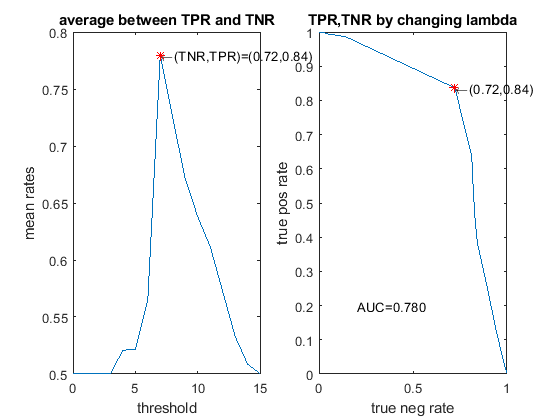

th = 0:15;
labels = depthError <=0.01;
true_pos_rate = zeros(size(th));
true_neg_rate = zeros(size(th));
for i = 1:numel(th)
    true_pos_rate(i) = sum((conf>=th(i)) .* labels) ./ sum(labels);
    true_neg_rate(i) = sum((conf<th(i)) .* (1-labels)) ./ sum(1-labels);
end

subplot(1,2,1)
mean_rate = mean([true_pos_rate;true_neg_rate]);
plot(th,mean_rate); xlabel('threshold');ylabel('mean rates');title('average between TPR and TNR');
[maxv,I] = max(mean_rate);
txt = strcat('\leftarrow', sprintf('(TNR,TPR)=(%.2f,%.2f)',true_neg_rate(I),true_pos_rate(I)));
text(th(I),mean_rate(I),txt)
hold on
plot(th(I),mean_rate(I),'r*')
t = th(I);
subplot(1,2,2)
plot(true_neg_rate,true_pos_rate); xlabel('true neg rate');ylabel('true pos rate');title('TPR,TNR by changing lambda');
AUC = trapz(true_neg_rate,true_pos_rate);
text(0.2,0.2,sprintf('AUC=%.3f',AUC))
hold on
plot(true_neg_rate(I),true_pos_rate(I),'r*')
txt = strcat('\leftarrow', sprintf('(%.2f,%.2f)',true_neg_rate(I),true_pos_rate(I)));
text(true_neg_rate(I),true_pos_rate(I),txt)

True Positive/Negative Rate - the ratio of positive/negative examples that were actually predicted as positive/negative with respect to all of the positive/negative examples.

Once I configured the weights to the pipe regs, I evaluated the confidence on several images. Nice example result:

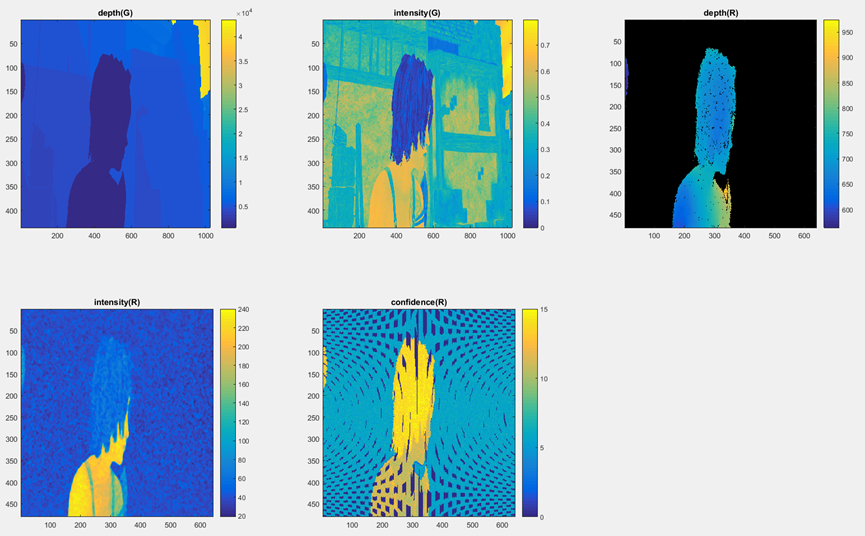

# Regs Configuration

To make all of the above work in the pipeline, I should used the following regs configuration:

% Confidence Regs

regs.DEST.confIRbitshift = uint8(6); % confIRbitshift determines which 6 bits to use from the IR value (12b -> 6b)
regs.DEST.confw1 = [int8(30),int8(0),int8(127),int8(-56)]; % Calculated scaled weights value. [dutyCycle,psnr,maxVal,IR].
regs.DEST.confw2 = [int8(0),int8(0),int8(0),int8(0)]; % Other weights path should be ignored.
regs.DEST.confv = [int8(0),int8(0),int8(0),int8(0)]; % All biases are zero.
regs.DEST.confq = [int8(1),int8(0)];% Keep the first channel. Zero the second.
dt = int16(13419); x0 = int16(-3528); % Activation maps [minPrev,maxPrev]->[-128,127]. dt and x0 are calculated as dtAct1,xoAct1
regs.DEST.confactIn = [x0,dt];
dt = int16(255); x0 = int16(-128);% Activation maps [-128,127]->[0,255]. dt and x0 are calculated as dtAct2,xoAct2
regs.DEST.confactOt = [x0,dt];
regs.JFIL.invUseGlobalConf = uint32(1);
regs.JFIL.invConfThr = uint8(th(I));